# 15. Automated XR2206 Frequency Control

© B. Rasnow 20 Apr 25 

## Objective

Design, model, and test Arduino control of an XR2206 function generator. With Arduino able to control or "sweep" the function generator's frequency, we can fully automate measurements in the frequency domain, such as [Bode Plots](https://en.wikipedia.org/wiki/Bode_plot). 

## 1. XR2206 datasheet

Google “XR2206 datasheet pdf” and look for a pdf, e.g., [https://www.sparkfun.com/datasheets/Kits/XR2206_104_020808.pdf](https://www.sparkfun.com/datasheets/Kits/XR2206_104_020808.pdf) A good first step is to peruse the sheet -- what are its main sections, how many pages, will a solution to automating frequency control jump out at us, or will it be buried deep? ... 

    In the Description, " The oscillator frequency can be linearly swept over a 2000:1 frequency range with an external control voltage" ... so that sounds encouraging. 

    The next thing I did was compare our kit's "schematic" with the datasheet's "Fig. 2, Basic test circuit":

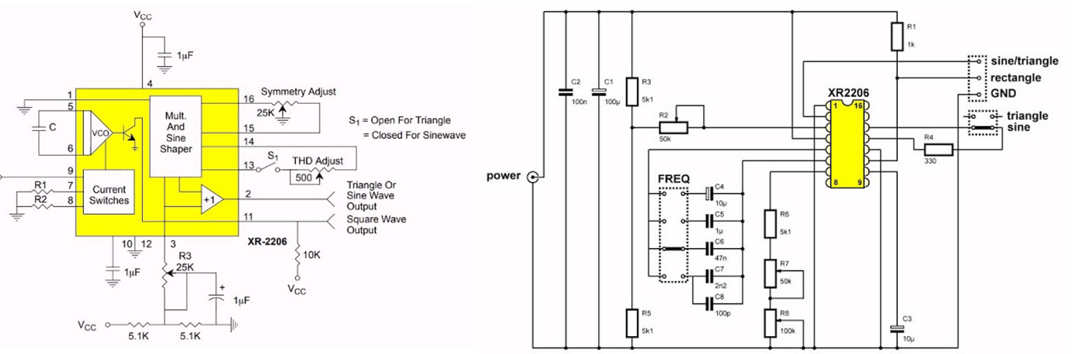

    Figure 1. Left: Figure 2 of the XR2206 datasheet showing the "basic test circuit", and (right) the "schematic" from our kit. 

- Parts have different numbers but similar values, e.g., R3 = 25k on the left is R2=50k on the right. Note how the center of the amplitude pot is connected to opposite terminals in the two schematics -- and our kit is backwards (at least if you want the amplitude to increase clockwise).

- R1=1k in our kit is 10k in the datasheet, and it shows the square wave is driven by an "[open-collector" switch](https://en.wikipedia.org/wiki/Open_collector) -- so R1 is a "[pull-up resistor](https://en.wikipedia.org/wiki/Pull-up_resistor)". The transistor conducts 50% of the time for a square wave, and when conducting, the current is 12V/1k = 12mA, so the average current = 6mA and average power = 12V*6mA = 72mW. The resistor can take 1/4W, so it should just get a little warm. The Maximum Power Rating for the XR2206 is 750mW (p.5 of the datasheet), so R1 uses 10% of it. It strikes me as unnecessary to waste that much power (just to lower the Zout of the square wave to 1k$\Omega$). 

- Datasheet R1||R2 = our R6+R7+R8 = timing resistor, with value ~5-155K.

- Datasheet C (between pins 5&6) = our C4-8 selected by the frequency jumper. 

- Schematic C1 and C2 are power supply filters, providing nearby charge for any sudden changes in load (e.g., when the square wave turns on/off. They correspond to the 1uF on pin 4 at the top. 

- Pin 10 is described as BIAS = internal voltage reference on p. 3 of the datasheet, and it is stabilized by 1uF in the datasheet and C3 = 10uF on our board. 

Overall, our kit is very similar to the datasheet's "basic test circuit", so we can expect the datasheet's descriptions should be largely relevant. 

### 1.1. *How* is the frequency controlled??

On p. 11, "PRINCIPLES OF OPERATION", it says: 

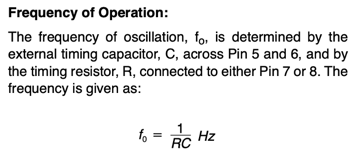

And just below that: 

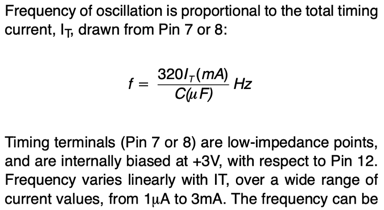

        Figure 2. Equations from XR2206 datasheet.

So there are (at least) 2 ways to control the frequency. The first equation we invoke by manually varying R = R6+R7+R8 with the 2 frequency pots R7 and R8 (in series), and select C with a jumper. But a current of $1\mu A - 3mA$ can also set the frequency ... I hope you are thinking ... "current mirror"!! And even better, recall from Chapter 11 that our current mirror was configured to shunt ~ $0-1mA$, so it might work without even *any* tweaking!! 

### 1.2. Testing the frequency equation

Before diving in, I feel it prudent to verify if the equations apply to our system. In general, the less one assumes and the more familiar one becomes with a system by testing and interacting with it, the more chance of success modifying it. Let's start with the frequency jumper in the 2nd position from the bottom. What's the value of C between XR2206-5&6? Surprise! The schematic shows 4 jumper positions and the board has ... 5. Looking underneath the board, the bottom jumper position connects to C4=10uF, the next one is C5=1uF, the middle is C6=47nF, ... and it looks like the schematic is wrong in showing C8=100pF in parallel with C7=2.2nF, in reality each C4-8 has a unique jumper position, starting with C4 at the bottom. Schematic errors are really annoying. They suck your time away trying to understand them. What about R in the equation? R = R6 + R7 +R8 = 5.1k + 50k pot + 100k pot in series, so `min(R)` = 5.1k and `max(R)` = 155k. What about `2*pi`? The corner frequency is given by $f_C = \frac{1}{2\pi RC}$ for a filter. But this isn't a filter, its a function generator integrated circuit, and its designers decided to rescale or normalize out the $2\pi$ from its characteristic equation. Connect your DMM to the SQU output, set the multimeter to measure frequency (Hz), and I measured the following range (substitute your results):

f2meas = [6.7 189.3]; % Hz measured on square wave with DMM
f2theory = 1 ./ ([155e3 5.1e3] * 1e-6) % max & min ohms * farads

f2theory =     6.4516  196.0784


err = (f2meas - f2theory) ./ f2theory

err =     0.0385   -0.0346


Likewise moving the frequency jumper to the center position: 

f3meas = [163 4565]; % Hz measured on square wave with DMM
f3theory = 1 ./ ([155e3 5e3] * 41.3e-9) % max & min ohms and farads

f3theory = 1.0e+03 *

    0.1562    4.8426


err = (f3meas - f3theory) ./ f3theory

err =     0.0434   -0.0573


15% errors aren't surprising with cheap pots and capacitors. 50% errors, or orders of magnitude should cause one to reexamine their model and math. We've confirmed that $2\pi$ is "baked into" the IC and the capacitors in positions 2 and 3 are ~ 1uf and 47nf respectively.

clear f*meas f*theory err % clean up

## 2. Preparing the function generator for automation

We need to carefully solder a jumper wire to the common node of XR2206's pin 7 and R6=5k to connect to our current miror, to shunt XR2206 pin 7. What if we connected the mirror instead to the other side of R6? Since XR2206-7 is at 3V, the maximum current we could shunt through the 5k resistor would be 3V/5k ~ 0.6mA, whereas if the mirror bypasses (shunts) R6, R7 and R8, we can control up to the full ~1mA of Fig. 2. With power turned off, an ohmmeter reveals the left side of R6 (nearest to XR2206-7) are connected, so that's where we must solder. The space is tight, so this will challenge your dexterity and soldering skills. 

- Your soldering iron should be hot enough to quickly melt solder, and clean of oxide and [dross](https://en.wikipedia.org/wiki/Dross) (new word?).

- With solder in one hand and iron in another (ignore the jumper wire for now), melt a small smooth ball of clean solder onto the left side of R6 (on top of the board). The angle of the iron will have to be nearly vertical to the board to avoid melting adjacent components.

- Cut the plug off one end of a jumper wire, strip ~1/16" = 1.5mm of insulation, and melt solder into the strands so a small ball of solder permeates the strands. (Do this away from R6, somewhere safe and convenient.)

- Trim the uninsulated solder permeated wire to ~1/16" beyond its insulation, in case the insulation shrunk back.

- Clean your iron once more and melt a ball of solder onto its tip. 

- Finally you're ready to connect them. There should enough solder on each item, so you only need to hold the iron with one hand and the wire with the other. Press the iron against R6 and the wire end (pressing the two soldered regions together). As soon as the solder melts, remove the iron. 

- After a few seconds for the solder to cool, pull on the wire and verify a robust mechanical connection was made. 

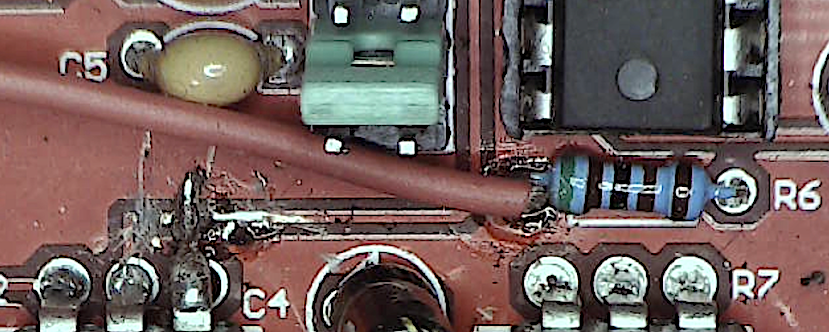 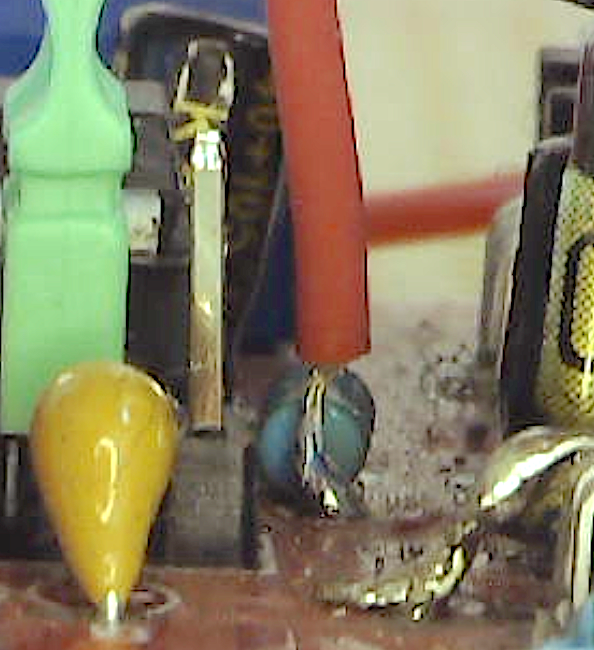

        Figure 3. Shunt jumper wire soldered to R6, top and side views.  Leads and traces of the amplitude pot R4 are also shown, cut and redirected so amplitude increases with clockwise rotation, vs. "backwards" as the board is constructed (note: the left 2 traces of R4 are connected by solder-bridge under the board).

## 3. Setting and measuring frequencies 

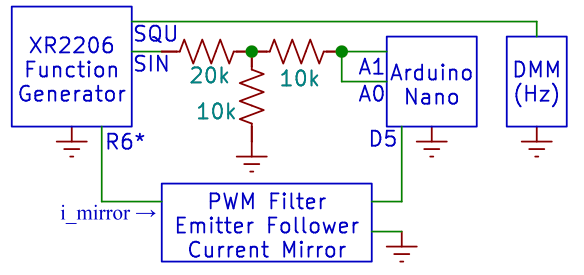

        Figure 4. Schematic for controlling frequencies with Arduino. Connection to R6* is via the shunt jumper in Fig. 3. The left 20k and 10k resistors can be substituted with a 2k and 1k voltage divider circuit. 

- Start with the frequency jumper in the middle position, and the frequency pots (R7 and R8) set to their minimum positions counter-clockwise (i.e., maximum values).  Your DVM set to Hz and connected to the SQUare wave should read around 138Hz and increase with the frequency pots. 

- Initialize a connection to the Arduino by running `oscope3`. Adjust the amplitude pot for maximum with low distortion, i.e, symmetrical peaks that aren't "clipping".  

- Connect the left side of R6 jumper (connected to XR2206-7) to the current mirror using a dedicated column on the solderless breadboard. Plug the jumper to the LM317's R2 into a different column, and the output of the LM317 in yet another -- so these wires won't accidentally touch something. 

- Verifying that the LM317 power output is no longer connected to the top red row of the breadboard, and plug the SIN output into that row. The voltage divider (20k+10k or 2k+1k) should still be there, if not then replace it and connect the SIN voltage divided by ~3 to A0 and A1 through a 10k "safety" resistor (Fig. 4). 

- Click the Run button on `oscope3`'s display and verify the system is working (Fig. 5).

- Stop the run and measure the mean amplitude of the signals, then edit `oscope3.m`'s `trim` function to use that threshold:

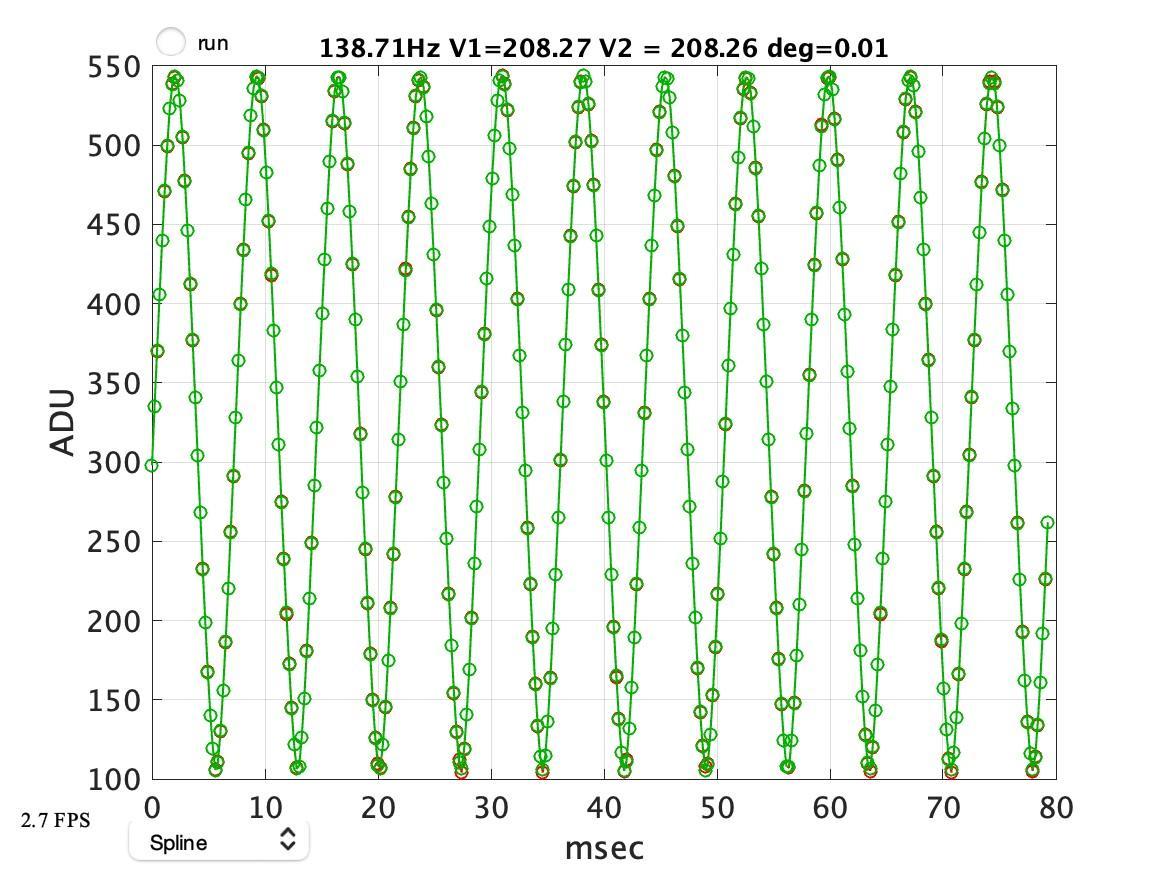

        Figure 5. `oscope3` display with the circuit in Fig. 2 as described above. 

If you don't see this, troubleshoot why not. Work your way back to what works (`oscope1`; does the DMM show a frequency on SQU; ... document and follow the clues. 

The following script performs an automated frequency sweep, storing the resulting frequencies in `fmeas`: 

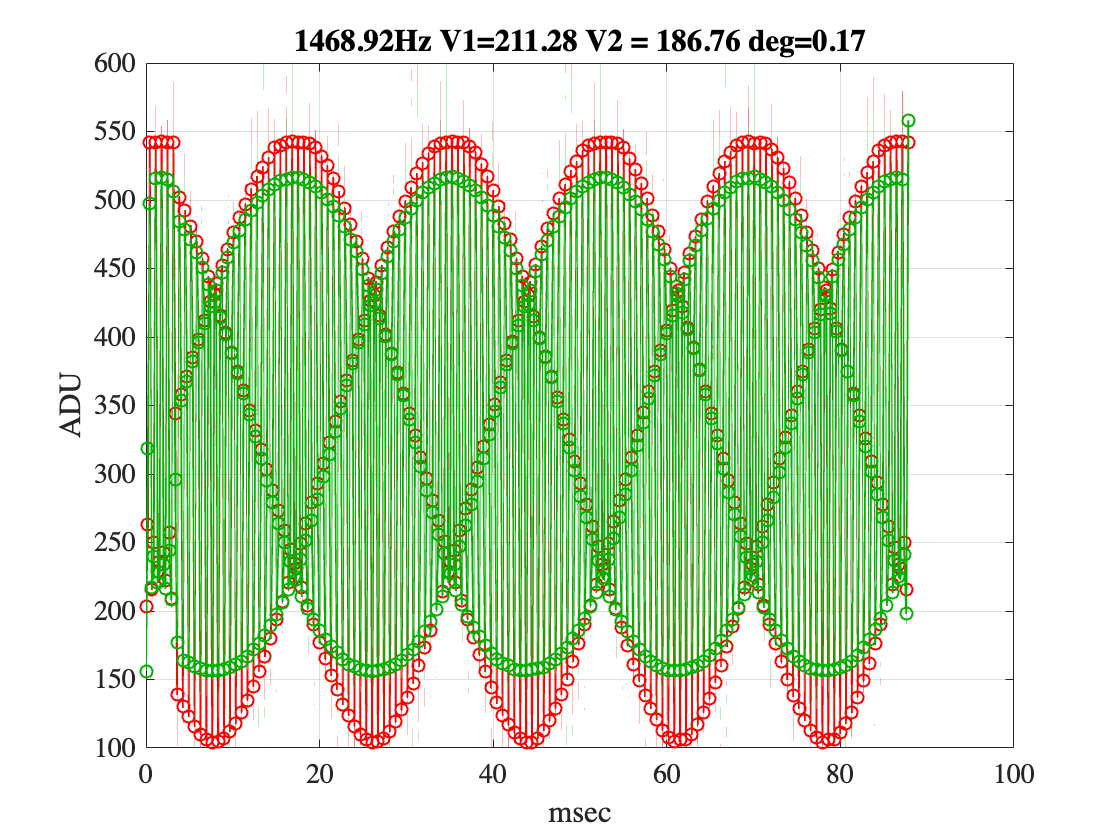

pwmVal = (55:5:255)';
fmeas = zeros(size(pwmVal)); 
for i=1:length(pwmVal)
    writeline(ard,['p' num2str(pwmVal(i))]);
    pause(.1); % extra time for the frequency to stabilize
    runOnce = true;
    oscope3; % --> new data = [A0 A1] ... and freq
    fmeas(i) = freq; 
end

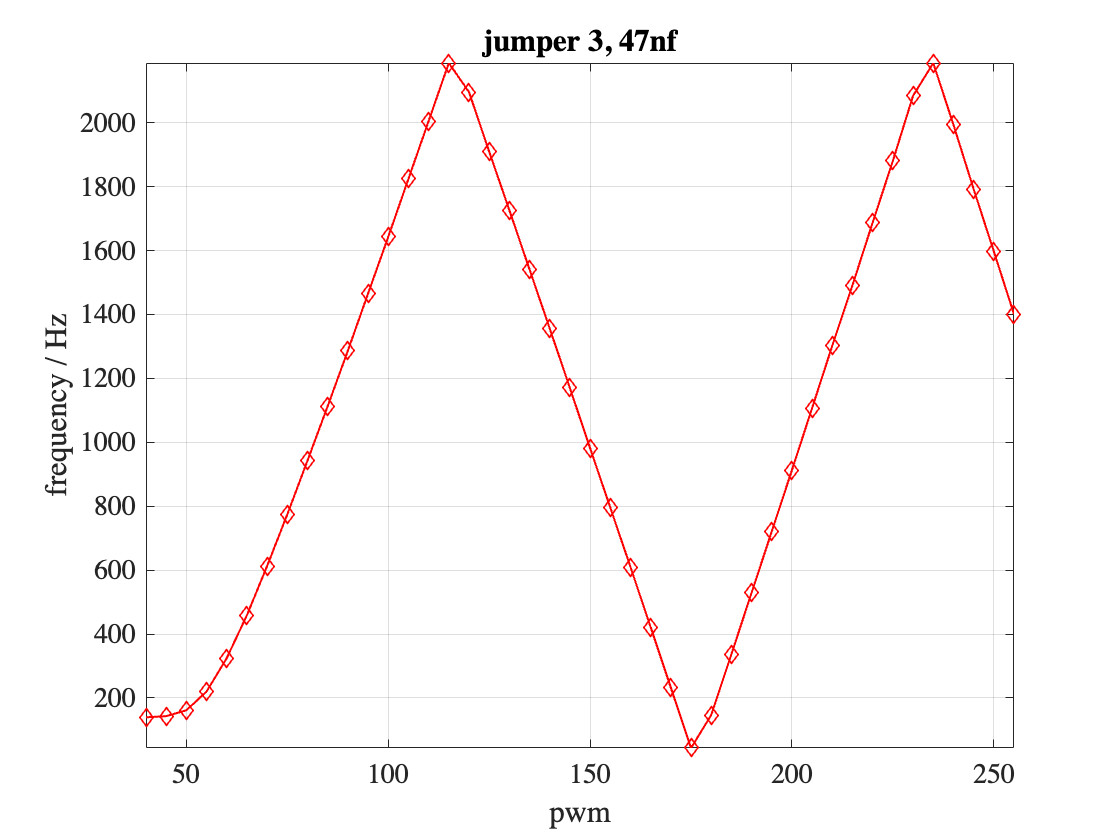

plot(pwmVal, fmeas, 'd-'); axis tight; grid;
xlabel('pwm'); ylabel('frequency / Hz'); title('jumper 3, 47nf'); 

        Figure 6. Automated frequency sweep with frequency pots fully counterclockwise, shows double aliasing.

We've certainly achieved automated frequency control, but not without issues and questions. Why is the *measured* frequency not monotonic? If you watched your DMM display during the sweep, it showed the frequency increased monotonically from (in my case) 139Hz - 7640Hz. But because of our discrete sampling rate, we don't measure frequencies above the Nyquist Frequency, $f_N$ = sample rate/2: 

fprintf('Nyquist frequency = %.1f Hz\n', sr/2)

Nyquist frequency = 2232.0 Hz


Frequencies above $f_N$ are *aliased* or "reflected" downward to `sr - f`. A second reflection occurs at `sr`, when the reflected frequencies hit zero, and invert a second time (  ~180 PWM). In spite of the aliasing, we can compute the highest measured frequency by counting the reflections. Three reflections correspond to $3f_N$ and add to that the "distance" (in frequency) from $f_N$ to the last point:

sr / 2 * 3 + (sr / 2 - fmeas(end))

ans = 7.5275e+03

which is <2% from the DMM frequency measurement. Aliasing is a common (and often devastating if unrecognized) systematic error that occurs when a signal is discretely sampled at too low a frequency. We can't sample any faster with our Arduino (easily), so we best avoid frequencies above the Nyquist freqency $f_N$ ~ 2.2kHz. However aliasing is a systematic, not random error. Aliasing makes a signal of frequency $f = f_N+f_1$ indistinguishable from a signal at frequency $f = 2f_N-f_1$. If both those frequencies were present in a signal, then the sampled signal would have their amplitudes hopelessly confounded. However, in our case where we have just one frequency present in the signal at a time (assuming harmonic distortion is low), in principle, we can tell whether the frequency we measure, $f$ is above or below $f_N$ (or a multiple of $f_N$). So we could measure signals much above $f_N$, although with care to unreflect and correct for the frequency ambiguity. 

Why does the frequency initially going up, whereas the LM317 curve went down? The equation for the LM317: Vout = 1.25 * (1+R2/R1) has the shunted R2 in the numerator. The equation for the XR2206 frequency: $f_0 = \frac{1}{RC}$ has the shunted R in the denominator. That explains the opposite slope -- one increases with R, the other decreases with R. It is also why we set the pots to their *maximum* values (fully *counterclockwise*, i.e., their *minimum* position corresponds to their maximum value).  

Can we explain the measured frequency range with theory? $f(Hz) = \frac{320 I_t(mA)}{C(\mu f)}$, C = .047$\mu f$ and $I_t$ has two extrema: ~1mA through the mirror and 3V/155k ~ 0.02mA through R6 and the two frequency pots. Using specified units:

320 * [3/155e3*1000 1] / .047

ans = 1.0e+03 *

    0.1318    6.8085


Within the uncertainty of C (up to 20%) and $i_{mirror} \approx 1mA$. 

## 4. Designing a single frequency band

How might we achieve a single frequency range of ~30Hz -- the minimum frequency we can measure a full period with our 400 sample buffer, to $f_N \approx 2.2$kHz, without moving the capacitor jumper? To do that, we'll need a different capacitor value. First, let's try to better estimate the maximum value of iMirror ~ 1mA. Solve for the $I_t$ in the second equation using the measured frequency at PWM = 255 and assuming C = 47nF: 

fmax = 7640; % Hz
C = .047; % microfarads
itmax = fmax * C / 320 % mA

itmax = 1.1221

What value of C would reduce fmax to $f_N$ ~ 2200? To lower fmax by 7700/2200, we'd have to raise C by the opposite ratio -- > 

Ctarget = C * fmax / (sr/2) % uF

Ctarget = 0.1609

How can we achieve that? The easiest solution I can think of (i.e., instead of buying a capacitor, desoldering an existing C from the board, and soldering in a new one), is to replace the jumper with a female-to-male pair of wires (included in our kit) and connect C's that we have. Capacitors in series act like impedances in parallel (recall, capacitors in parallel add their capacitance -- like resistors in series), so we need to start with a C > `Ctarget`, i.e., C5 = 1uf in the 2nd position. If we connect in series with C5 an 0.1uf, the capacitance will be <0.1, but if we put 2 0.1uFs in parallel, then:

Cp = zp(1, .2) % uF

Cp = 0.1667

Pretty close to our goal. We can estimate the frequency range this would achieve: 

f3 = 320 * [3/155 itmax]/Cp; 
fprintf('%fuf --> %.1f-%.1fHz', Cp, min(f3), max(f3))

0.166667uf --> 37.2-2154.5Hz

Here's what it looks like when connected. 

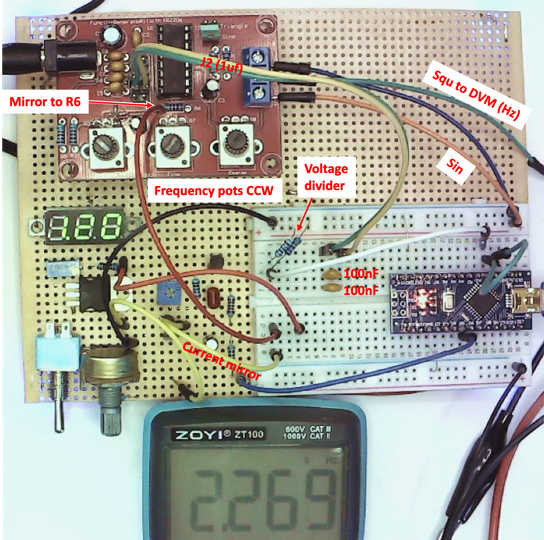

        Figure 8. 2x100nF capacitors (in parallel) connected in series with C5=1uf on the board through a (yellow/green) pair of female-male jumper wires. 

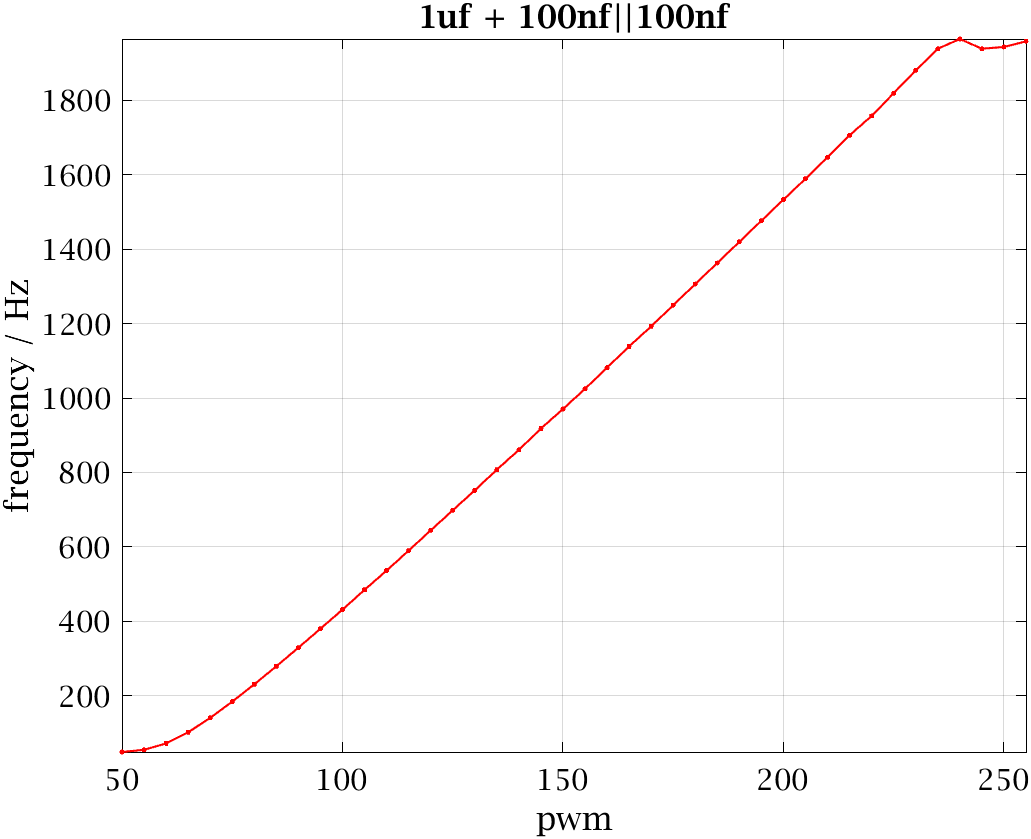

        Figure 9. Frequency sweep with the configuration of Figure 7. 

We're still seeing some non-monotonic behavior at the top. Two (easy) ways to fix this: 1) don't go there, i.e., limit (in software) `pwm` or 2) add more C in parallel to our 200nF. In particular, if you haven't lost the frequency jumper yet ;-), then put it across the middle position (and it won't get lost). That should add C6=47nF in parallel.

Cp = zp(1, .247); % 47nf in series with 2x100nf
f3 = 320 * [3/155 itmax]/Cp; 
fprintf('%.3fuf --> %.1f - %.1fHz', Cp, min(f3), max(f3))

0.198uf --> 31.3 - 1812.8Hz

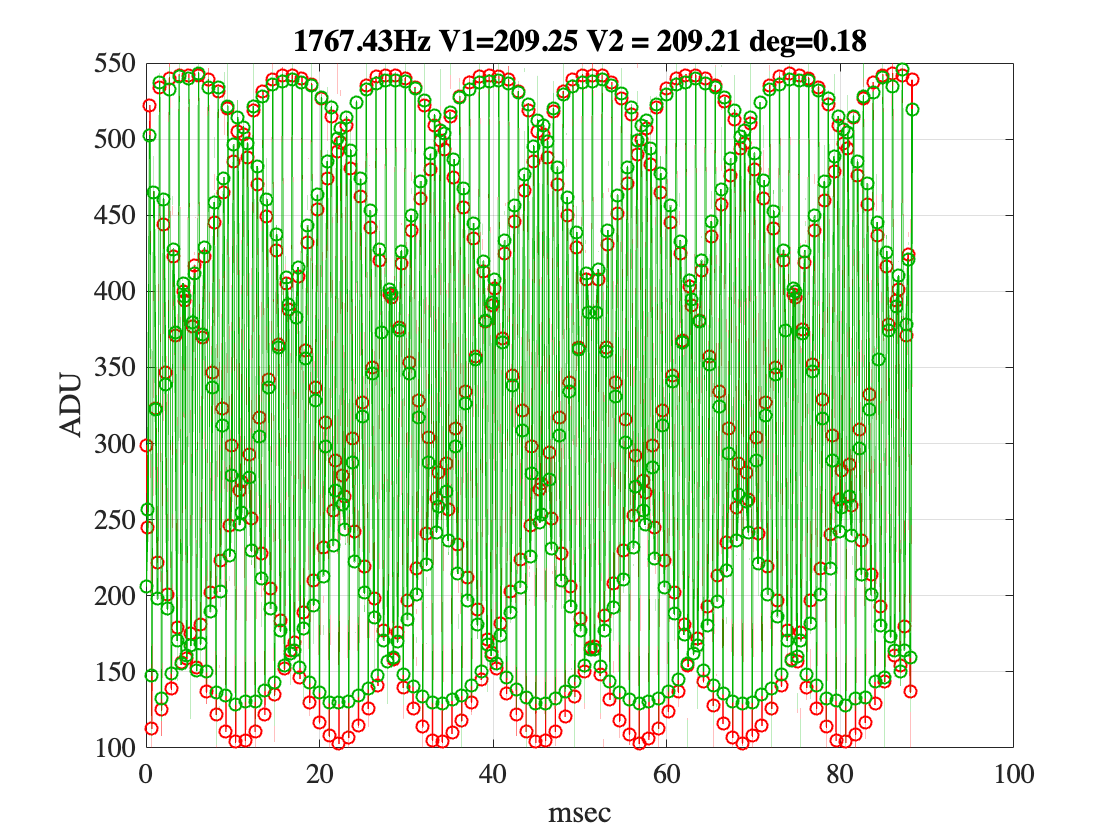

pwmVal = (40:5:255)';
fmeas = zeros(size(pwmVal));
for i=1:length(pwmVal)
    writeline(ard,['p' num2str(pwmVal(i))]);
    pause(.2); % time for the frequency to stabilize
    runOnce = true;
    oscope3; % --> new data = [A0 A1] ... and freq
    fmeas(i) = freq; 
end

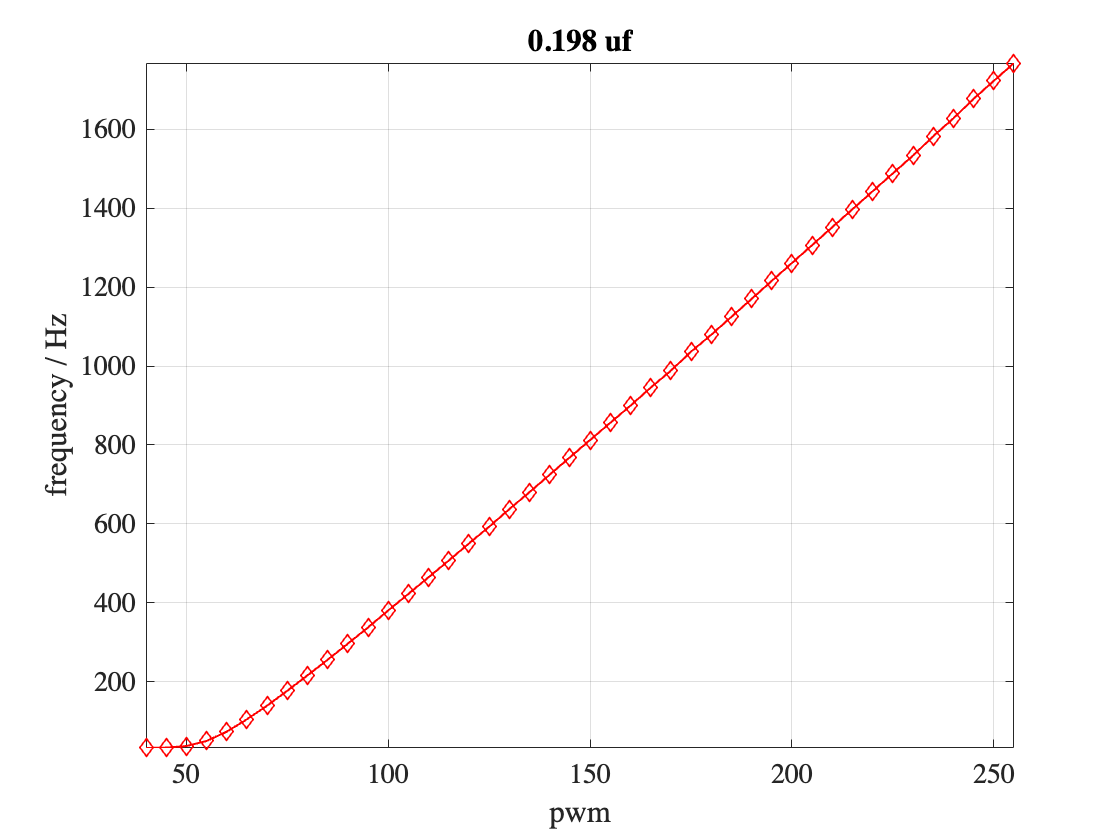

figure; 
plot(pwmVal, fmeas, 'd-'); axis tight; grid;
xlabel('pwm'); ylabel('frequency / Hz'); 
title(sprintf('%.3f uf', Cp)); 

Figure 10. Adding frequency jumper 3 in parallel with 2x100nF reduced the frequency range to 

maintain monotonicity.

clear C* f3 itmax fmax

## 6. Building a calibrated software interface

I noticed empirically that a step down in frequency stabilizes much faster than a step up. Not sure why, but an easy "fix" is to start at PWM=255, and move downward. I also noticed the amplitude of A1 << A0 at high frequencies -- even though they are jumpered together. This turned out to be an artifact of `spline`, switching to Fourier deskewing eliminated it (it has no effect on our data as we're just focusing on $f$, not $A$ now.  Final warning, sometimes I hit the Stop button or Control-C to stop a script, and that can leave data in the serial buffer. The buffer is "[first in-first out" or FIFO](https://en.wikipedia.org/wiki/FIFO_(computing_and_electronics)), so the next read returns old data corresponding to different conditions -- which can be difficult and frustrating to debug. At first I thought of giving you a warning, maybe in bold font to make sure the serial buffer is empty, i.e.

ard.NumBytesAvailable % should be zero

ans = 0

But a much better solution is to automatically empty (`flush`) the buffer. Why depend on human memory to do something when the computer can/will do it every time?

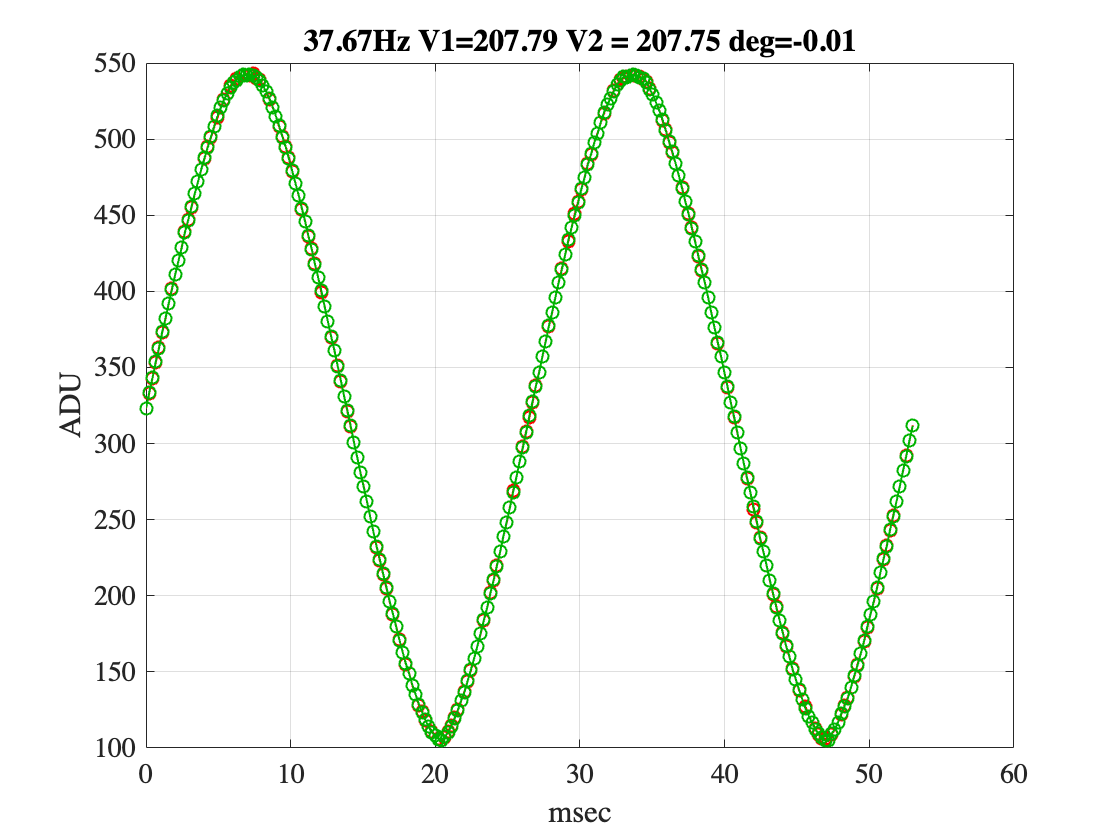

flush(ard) % force buffer to empty
pwmVal = (255:-5:50)';
writeline(ard,'p 255'); pause(2); % ideally pause 1 minute!
fmeas = zeros(size(pwmVal));
for i=1:length(pwmVal)
    writeline(ard,['p' num2str(pwmVal(i))]);
    pause(.2); % time for the frequency to stabilize
    runOnce = true;
    oscope3; % --> new data = [A0 A1] ... and freq
    fmeas(i) = freq; 
end

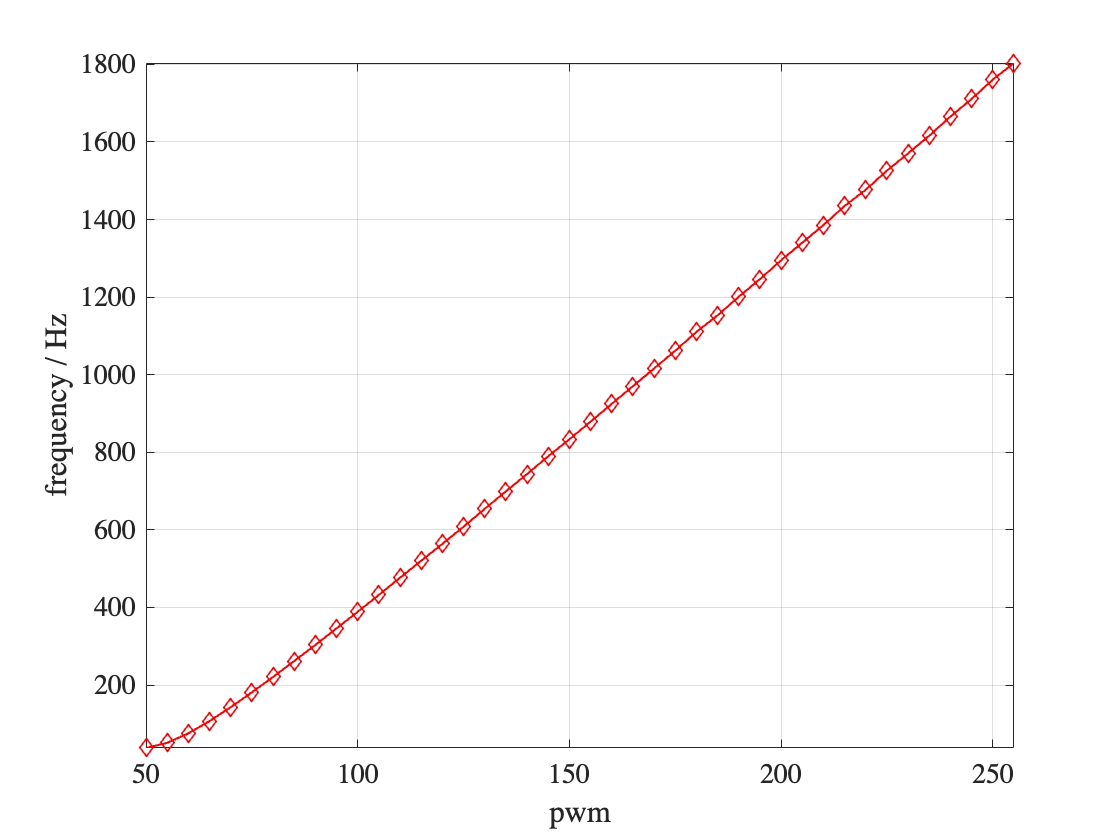

writeline(ard,'p 255'); % expect to repeat ... 
plot(pwmVal, fmeas, 'd-'); axis tight; grid;
xlabel('pwm'); ylabel('frequency / Hz'); 

To find a low order polynomial that fits Fig. 10, excluding the initial (last -- because frequency decremented) pwm values:

indx = 1:length(pwmVal)-1; % skiping lowest f 
p1 = polyfit(pwmVal(indx), fmeas(indx), 1); % 1st order fit
p2 = polyfit(pwmVal(indx), fmeas(indx), 2); % 2nd order fit
p3 = polyfit(pwmVal(indx), fmeas(indx), 3); % 3rd order fit
p4 = polyfit(pwmVal(indx), fmeas(indx), 4); % 4th order fit
p6 = polyfit(pwmVal(indx), fmeas(indx), 6); % 6th order fit

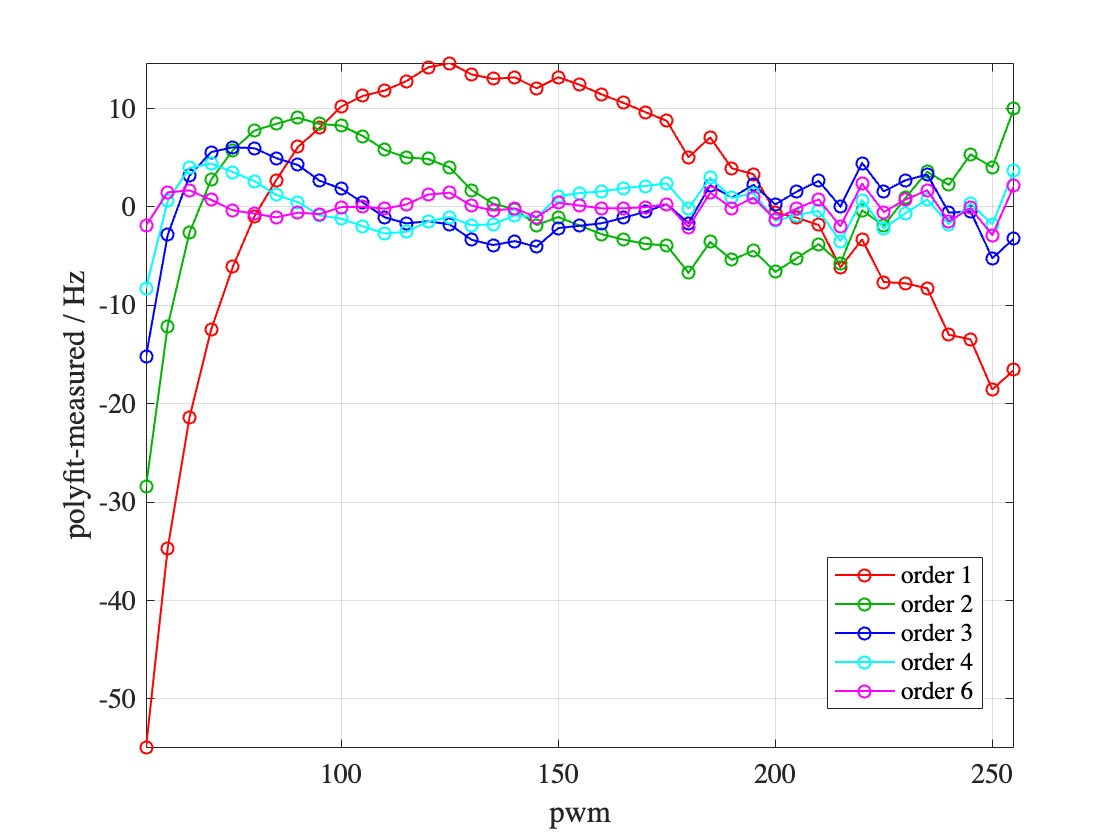

% difference plots
df1 = polyval(p1, pwmVal(indx)) - fmeas(indx);
df2 = polyval(p2, pwmVal(indx)) - fmeas(indx);
df3 = polyval(p3, pwmVal(indx)) - fmeas(indx);
df4 = polyval(p4, pwmVal(indx)) - fmeas(indx);
df6 = polyval(p6, pwmVal(indx)) - fmeas(indx);
plot(pwmVal(indx), [df1 df2 df3 df4 df6],'o-');
xlabel('pwm'); ylabel('polyfit-measured / Hz'); axis tight; grid;
legend('order 1','order 2','order 3','order 4','order 6','location','best')

        Figure 11. Error plots of various ordered polyfits. 

rms([df1 df2 df3 df4 df6])

ans =    14.5332    6.9061    3.7737    2.3627    1.1555


Although Fig. 10 *looks* linear to the eye, the parabolic error of the 1st order (linear) fit suggests we can do better with a higher order polynomial. The 2nd order fits the parabolic error, leaving a notable cubic polynomial error, etc. Higher order fits reduce the error. However what we really want is the inverse -- a polynomial, $pwm = \Sigma_{n=1}^6 a_n * (frequency)^{6-n}$ (MATLAB's index ordering), so let's just do that with a 6th order fit:

clear p2 p3 p4 p6 df* % clean up workspace a little
pf = polyfit(fmeas(indx), pwmVal(indx), 6);

fprintf('%e\t',pf)

-1.966212e-17	1.205307e-13	-2.910824e-10	3.526133e-07	-2.280964e-04	1.873013e-01	4.669630e+01	

The huge range of coefficients resulted in the warning, so let's "try centering and scaling". A little trial-and-error led to 1) rescale the frequency to kHz, $f \rightarrow f/1e3$ and 2) center the pwm values $PWM \rightarrow PWM-150$. 

pf = polyfit(fmeas(indx)/1000, pwmVal(indx)-150, 6);
fprintf('%.3f ',pf)

-19.662 120.531 -291.082 352.613 -228.096 187.301 -103.304 

All coefficients are now of comparable magnitude (and the Warning vanished), and we'll just undo those transformations inside `freq2pwm`. You might wish to` >> edit volts2pwm`, `Save as ...` and modify it as follows (don't forget to replace `pf` in the function with your polynomial coefficient values):

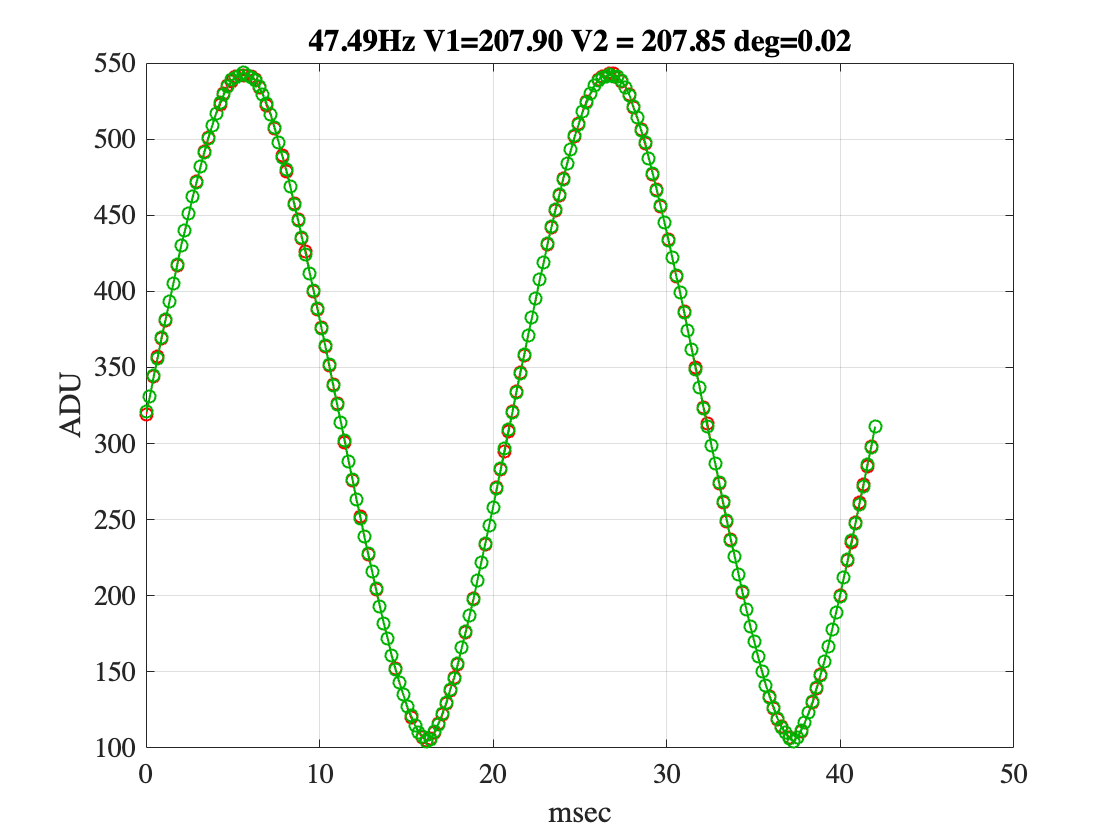

function pwmVal = freq2pwm(freq, ard)
% function pwmVal = freq2pmw(freq, ard)
% return pwm value corresponding to freq (Hz) for XR2206 arduino control
% using the current mirror circuit built for the LM317 and volts2pwm
% if a serial port is passes as 2nd arg then sends p command 

pf = [-19.662  120.531  -291.082  352.613  -228.096  187.301  -103.304];
pwmVal = constrain(round(polyval(pf,freq/1e3))+150,0,255);
if nargin == 2, writeline(ard,['p' num2str(pwmVal)]); end
end

function x = constrain(x, xmin, xmax)

% Arduino's constrain function

Elapsed time is 28.975517 seconds.


x(x<xmin) = xmin;
x(x>xmax) = xmax;
end

*Programming note:* I previously put the above function in a "Code Appendix" section at the end of this `LiveScript` file. But I also was editing a `freq2pwm.m` file in my PATH -- and errors remained high and nothing was changing ... because MATLAB executes code by first looking for functions at the bottom of the current `.mlx` file, then in the current directory, and then proceeds through folders in the PATH. It took a frustrating while to figure out why my changes weren't having an effect. Querying `>> which freq2pwm` didn't give the right answer either, because *from the command line*, the executable function was the version in the PATH that I was editing, but code executed *from* the `LiveScript` was a different copy of the function at the end of the file. I've since deleted the Appendix and put the code in the non-executable "Code Example" block just above. Programming (and debugging) can be tricky!! 

## 7. Measuring performance and errors

Let's validate `freq2pwm` with e.g. 50 frequencies and make a difference plot, Again we start near the highest frequency and decrement because the function generator (for unknown reasons) converges faster in that direction.

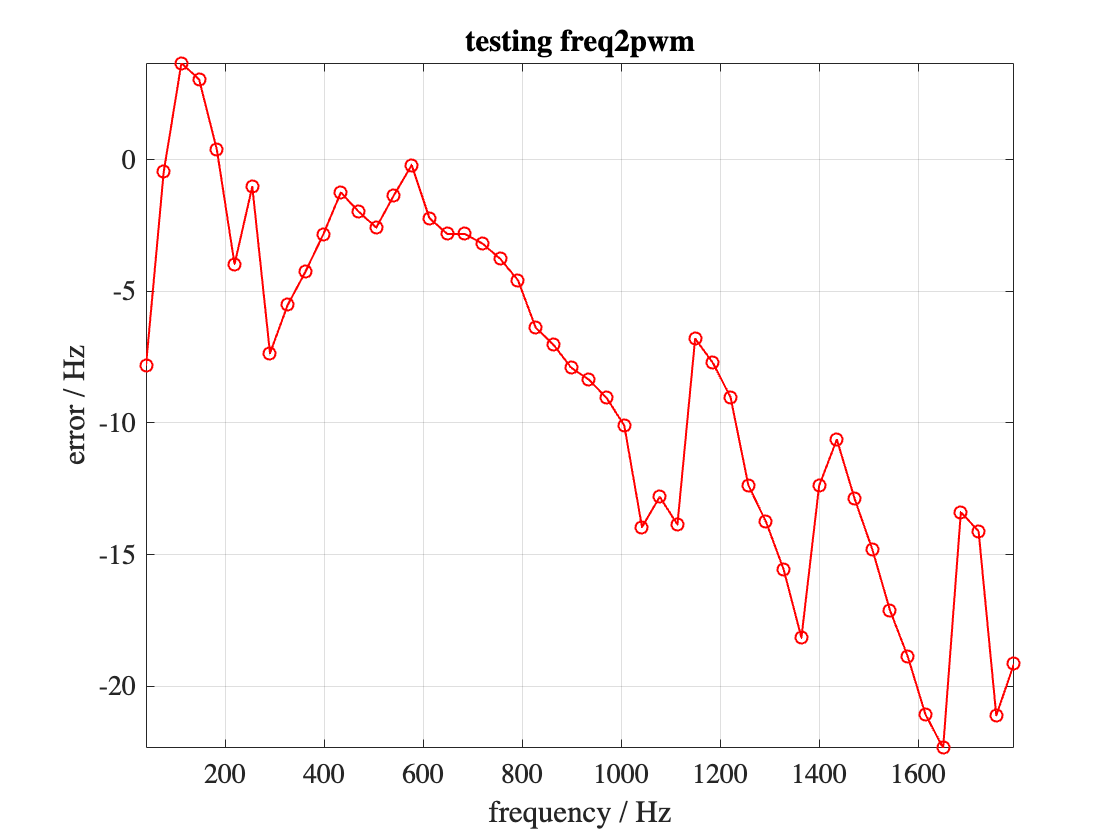

flush(ard);
writeline(ard, 'p 255'); pause(5); 

tic;
ftarget = linspace(max(fmeas)-10, min(fmeas)+2, 50)';
fmeas2 = zeros(size(ftarget));
for i=1:length(ftarget)
    freq2pwm(ftarget(i), ard);
    pause(.2);
    runOnce = true;

rms relative frequency error = 0.026

    oscope3; % --> new data = [A0 A1]
    fmeas2(i) = freq; 
end

rms relative frequency error from 75.9Hz - 1812.7Hz = 0.011

toc 
err = ftarget - fmeas2; 
figure;
plot(ftarget, err, 'o-'); axis tight; grid;
xlabel('frequency / Hz'); ylabel('error / Hz'); 
title('testing freq2pwm')

Figure 12. Frequency errors for 50 target frequencies. 

An error of 10Hz out of 100 is 10%, but  10Hz/1000Hz = 1%. These errors won't matter if we always measure the actual frequency of the data. `freq2pwm` gets us close and we measure and use exactly what we got, concurrently measuring amplitudes and phases. More concerning maybe settling time and stability, suggested by the large initial error. We could randomize the order of the frequencies, thus making larger and smaller frequency jumps. But as we'll see in the next experiment, sweeping frequency in one direction generally works fine. 

Another feature of the difference plot (Fig. 12) is that the remaining error *should* *be* wiggly. If our system is stable in time, then `polyfit` should account for all the wiggles to the order we fit. Since we fitted a 6th order polynomial, the remaining error should be dominated by 7th and higher order polynomials -- i.e., wiggly. The XR2206 is not the most stable oscillator. Although the datasheet claims temperature stability of "<50ppm/°C", that's at a particular low value of R (and high current), and stability is much, much worse at other values -- Fig. 9 (p. 11) of the datasheet. Also $f = 1/(RC)$ and both $R$ but more likely $C$ could vary with temperature. Cheap capacitors (slightly) change their shape with temperature (and humidity) ... So there can be many factors leading to errors of the magnitude we're measuring in Fig. 12. 

One last thing, it's always better to be quantitative instead of vague, "the error is {reasonable, not too big, ....}" is ambiguous. So I computed the relative frequency error for each frequency and computed its `rms value:`

relErr = err ./ fmeas2;
fprintf('rms relative frequency error = %.3f', rms(relErr))

Thus we can explicitly state that our frequency controller sets the function generator to +-<3% of its target frequency. Rms more heavily weights the big errors, so eliminating the lowest frequency from the domain (which the polynomial didn't fit well), we find: 

fprintf('rms relative frequency error from %.1fHz - %.1fHz = %.3f', ...
    fmeas2(end-1), fmeas2(1), rms(relErr(1:end-1))) % frequencies decrease

So 2% of the 3% rms error was from the one lowest frequency, and the rest are on average (`rms`) within <1% of target. I feel good about that!!  

Let's save our workspace in case we forgot something we'll want to check later: 

`>> save automatedFgenData`

## 8. Conclusions

Again, we covered an enormous amount of intellectual territory in this unit. Few things worth doing are easy, and this certainly was hard. We constructed a function, `freq2pwm(freq, ard)` which essentially "turns the frequency knobs" on the function generator without using hands. To do this, we had to take a deep dive into another complicated datasheet, avoiding the irrelevant stuff, and focusing on the relevant 2 equations between Figs. 1-2 above. Frequency is proportional to current from pin 7, and the slope of the frequency $\propto  C^{-1}$. We verified that our function generator circuit was similar to the datasheet's circuit, and then confirmed that these equations were relevant. We discovered that high frequencies alias with our slow discrete data acquisition system, and "reflect" to appear as lower frequencies, and thus we chose to avoid $f>f_{Nyquist}$ = `sr/2`. We used trial-and-error empirically, but mostly with the equations for series and parallel capacitances (with our function `zp.m`) to find and assemble a capacitance that controlled the frequency over a wide usable range. Modeling the measured frequency response as a polynomial led us to recognize ill-conditioned polynomials, which we fixed by normalizing the parameters, making them more symmetric and closer to 1 by shifting (subtraction) and scaling (division). Oh, and we can add to the lessons that hardware circuits like a current mirror can be "recycled" sort of like computer code can, to serve purposes that they weren't initially designed to serve. That's pretty cool, huh? 

What else did you learn from this adventure?? 